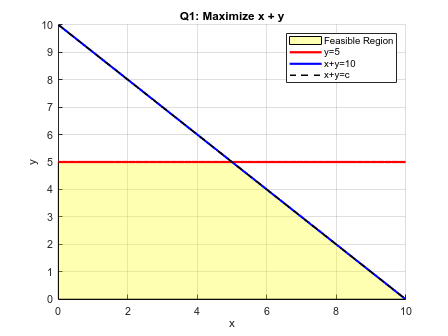

clc;
clear all;

x = linspace(0, 10, 100);
y1 = 5 * ones(size(x));             
y2 = 10 - x;                        

figure;
hold on;
fill([0 0 5 10], [0 5 5 0], 'y', 'FaceAlpha', 0.3);
plot(x, y1, 'r', 'LineWidth', 2);
plot(x, y2, 'b', 'LineWidth', 2);

f = @(x) 10 - x;
plot(x, f(x), 'k--', 'LineWidth', 1.5);


xlabel('x'); ylabel('y');
title('Q1: Maximize x + y');
legend('Feasible Region','y=5','x+y=10','x+y=c');
axis([0 10 0 10]);
grid on;

## qN2

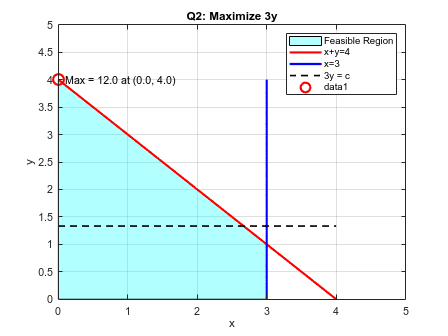

clc;
clear all;

X = [0 3 3 0];
Y = [0 0 1 4];

% Plot feasible region
figure;
fill(X, Y, 'c', 'FaceAlpha', 0.3); % Shaded feasible region
hold on;

% Plot constraints
x = linspace(0, 4, 100);
y1 = 4 - x;         % x + y = 4
x3 = 3 * ones(size(x)); % x = 3
plot(x, y1, 'r', 'LineWidth', 2); % x + y = 4
plot(x3, x, 'b', 'LineWidth', 2); % x = 3
f = @(x) (4/3) * ones(size(x)); % Constant y line
plot(x, f(x), 'k--', 'LineWidth', 1.5); % sample 3y = c line
xlabel('x'); ylabel('y');
title('Q2: Maximize 3y');
legend('Feasible Region', 'x+y=4', 'x=3', '3y = c');
axis([0 5 0 5]);
grid on;
vertices = [0 0; 3 0; 3 1; 0 4];
values = 3 * vertices(:,2); % 3y for each vertex
[max_val, idx] = max(values);
max_point = vertices(idx,:);
plot(max_point(1), max_point(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
text(max_point(1)+0.1, max_point(2), sprintf('Max = %.1f at (%.1f, %.1f)', max_val, max_point(1), max_point(2)));

## Qn3

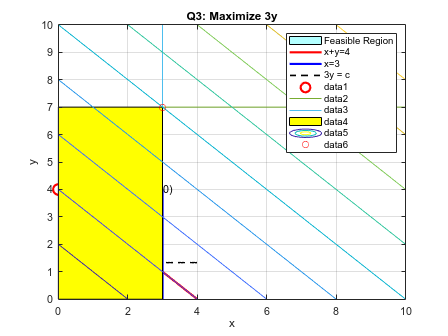

x = linspace(0, 10);
y1 = 7;
y2 = x;
title('Q3: Maximize 3y');
plot(x, ones(size(x))*y1);
hold on
plot(ones(size(y2))*3, y2);

fill([0 3 3 0], [0 0 7 7], 'y');

[X,Y] = meshgrid(0:0.5:10);
Z = X+Y;
contour(X,Y,Z);
plot(3,7,'ro');

axis([0 10 0 10]);
hold off

## Qn4

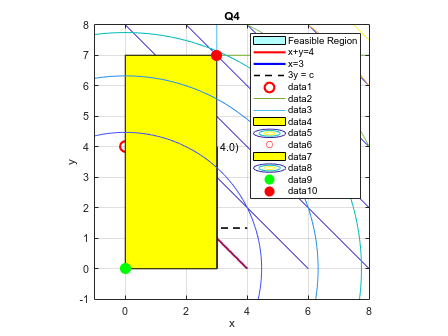

axis equal
hold on

title('Q4');
fill([0 3 3 0], [0 0 7 7], 'y');

[X,Y] = meshgrid(-1:0.1:8, -1:0.1:8);
Z = X.^2 + Y.^2;
contour(X,Y,Z);

plot(0,0,'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(3,7,'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

axis([-1 8 -1 8]);
grid on
hold off 